# Observations

This script generates the figure that shows observational data.

% Standard MATLAB initialization
clear; clc; clf; % reset workspace
rng default; % explicitly seed random numbers (for reproducibility)

% Ensure the following line is not commented out to display version information
% ver

## Define Styles

% All styling variables are placed in the global workspace so they can be
% conveniently accessed by plotting functions. Suppress the MATLAB warning.
global FontName; %#ok<*GVMIS>
FontName   = "Arial";

global C4Color C12Color MixedColor LasBColor LasIColor RhlIColor;
C4Color    = [237,176,129]/255;
C12Color   = [193,65,104]/255;
MixedColor = [229,113,94]/255;
LasBColor  = [44,49,114]/255;
LasIColor  = [165,205,144]/255;
RhlIColor  = [52,133,141]/255;

% Custom color maps adapted from seaboarn: 
%  - Watson ML. “seaborn: statistical data visualization.” Journal of Open Source
%  - Software 2021 Apr 06;6(60): doi: 10.21105/joss.03021.
global crest flare; %#ok<NUSED>
load("crest.mat");
load("flare.mat");

## Load Data and Model Parameters

% Retrieve model parameter estimates. Since these values are
% used throughout the notebook, they're stored as global data
% to avoid Workspace clutter and verbose function signatures.

loadModel();
% global Model; % uncomment this line to expose model to workspace

lasI = readData("LasIObservations.csv");
rhlI = readData("RhlIObservations.csv");


## Create the Plot

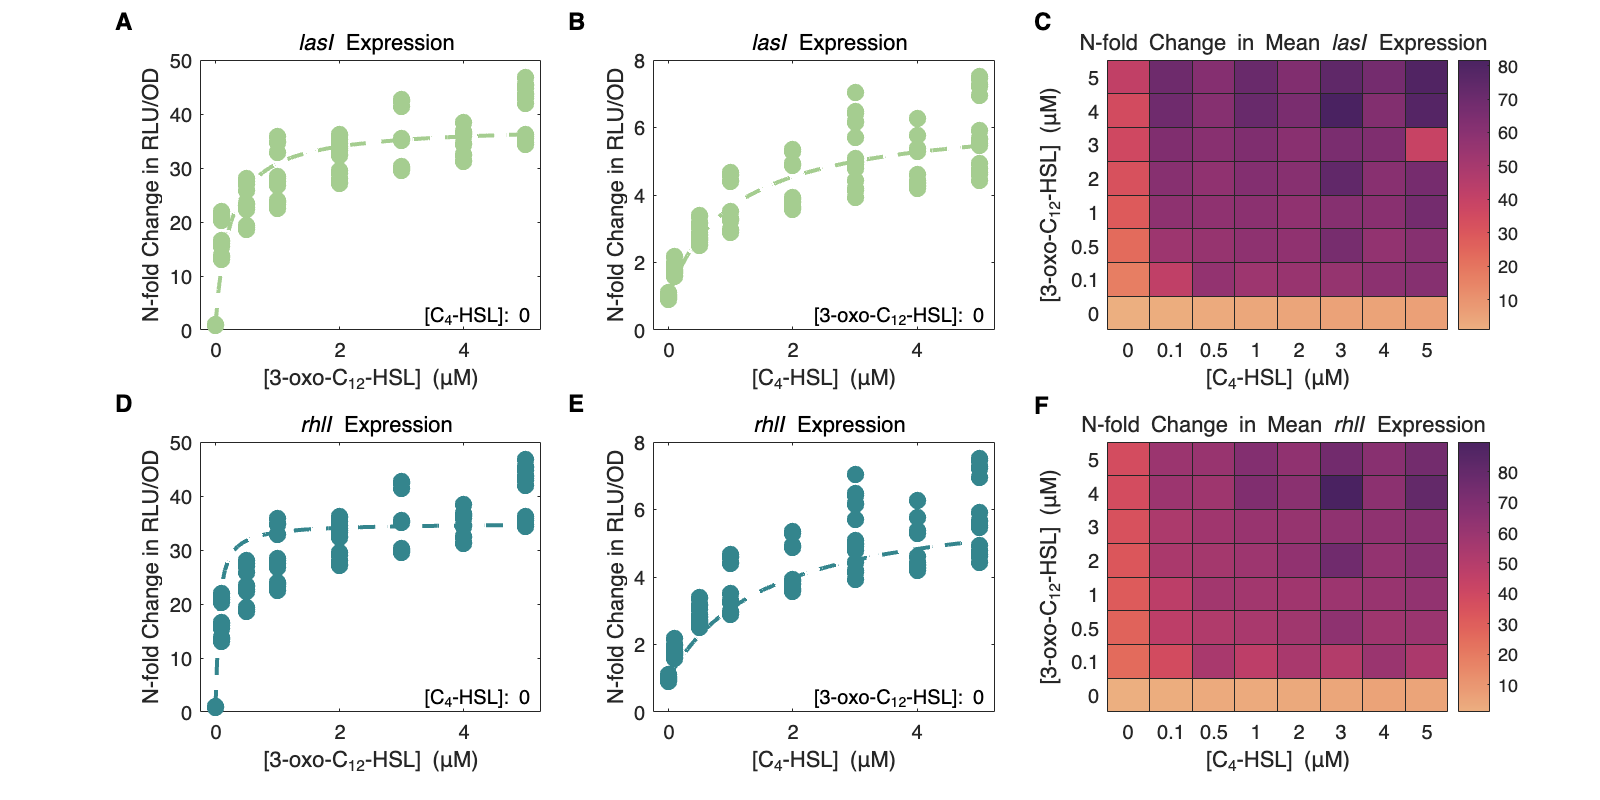

fig = figure;
fig.Position(3:4) = [800, 400];  % [width, height]

observationsPlot = tiledlayout(2, 3);

nexttile;
plotSingleSignal(Data=lasI, Gene="lasI", Signal="c12", Panel="A");

nexttile;
plotSingleSignal(Data=lasI, Gene="lasI", Signal="c4", Panel="B");

nexttile;
plotMultiSignal(Data=lasI, Gene="lasI", Panel="C");

nexttile;
plotSingleSignal(Data=lasI, Gene="rhlI", Signal="c12", Panel="D");

nexttile;
plotSingleSignal(Data=lasI, Gene="rhlI", Signal="c4", Panel="E");

nexttile;
plotMultiSignal(Data=rhlI, Gene="rhlI", Panel="F");

exportgraphics(observationsPlot, "../Prefigures/observations.png", Resolution=600);
exportgraphics(observationsPlot, "../Prefigures/observations.pdf", ContentType='vector');

## Local Functions

function [data, meanData] = readData(fileName)
    arguments (Input)
        fileName string % file name without path
    end
    arguments (Output)
        data table      % table of all observations
        meanData table  % table of mean expression per replicate
    end

    data = readtable("../Models/" + fileName);
    meanData = groupsummary(data, ["c12","c4"], "mean", "rlu_od");
    meanData = renamevars(meanData, "mean_rlu_od", "rlu_od");
    meanData.GroupCount = [];
end

function loadModel()
    global Model;
    global a10 a11 K11 a12 K12 a112 K112 K121;
    global a20 a21 K21 a22 K22 a212 K212 K221;
    global a30 a31 K31 a32 K32 a312 K312 K321;

    Model = readtable("../Models/Summary.csv", 'ReadRowNames', true);
    GenesRegex = regexpPattern('lasI|rhlI|lasB');
    Model.Properties.RowNames = cellfun(@(str) ...
        extract(str, GenesRegex), Model.Properties.RowNames);
    Model = fillmissing(Model, 'constant', 0);

    a10 = Model{"lasI", "a0"};
    a11 = Model{"lasI", "a_c12"};
    K11 = Model{"lasI", "K_c12"};
    a12 = Model{"lasI", "a_c4"};
    K12 = Model{"lasI", "K_c4"};
    a112 = Model{"lasI", "aQ"};
    K112 = Model{"lasI", "KQ_c12"};
    K121 = Model{"lasI", "KQ_c12"};

    a20 = Model{"rhlI", "a0"};
    a21 = Model{"rhlI", "a_c12"};
    K21 = Model{"rhlI", "K_c12"};
    a22 = Model{"rhlI", "a_c4"};
    K22 = Model{"rhlI", "K_c4"};
    a212 = Model{"rhlI", "aQ"};
    K212 = Model{"rhlI", "KQ_c12"};
    K221 = Model{"rhlI", "KQ_c12"};

    a30 = Model{"lasB", "a0"};
    a31 = Model{"lasB", "a_c12"};
    K31 = Model{"lasB", "K_c12"};
    a32 = Model{"lasB", "a_c4"};
    K32 = Model{"lasB", "K_c4"};
    a312 = Model{"lasB", "aQ"};
    K312 = Model{"lasB", "KQ_c12"};
    K321 = Model{"lasB", "KQ_c12"};
end

function handle = plotSingleSignal(args)
    arguments
        args.Data table
        args.Gene string
        args.Signal string
        args.Panel string = ""
    end

    global LasIColor RhlIColor;
    global a10 a11 a12 K11 K12; % lasI parameters (i=1)
    global a20 a21 a22 K21 K22; % rhlI parameters (i=2)

    data   = args.Data;
    gene   = args.Gene;
    signal = args.Signal;
    panel  = args.Panel;

    if gene == "lasI"
        color = LasIColor;
        a0 = a10;
        if signal == "c12"
            a = a11;
            K = K11;
        else
            a = a12;
            K = K12;
        end
    else
        color = RhlIColor;
        a0 = a20;
        if signal == "c12"
            a = a21;
            K = K21;
        else
            a = a22;
            K = K22;
        end
    end

    if signal == "c12"
        signalName = "3‑oxo‑C_{12}‑HSL";
        nullSignal = "c4";
        nullSignalName = "C_{4}‑HSL";
    else
        signalName = "C_{4}‑HSL";
        nullSignal = "c12";
        nullSignalName = "3‑oxo‑C_{12}‑HSL";
    end
    

    minRange = min(data.(signal));
    maxRange = max(data.(signal));
    baseline = mean(data{data.c4 == 0 & data.c12 == 0, 'rlu_od'});

    hold on;

    % plot observations as points
    data = data(data.(nullSignal) == 0, :);
    xPts = data.(signal);
    yPts = data.rlu_od / baseline;
    handle = scatter(xPts, yPts, 75, color, "filled");

    % plot model predictions as a line
    x = linspace(minRange, maxRange, 100);
    y = (a0 + a * x ./ (K + x)) / a0;
    plot(x, y, "--", Color=color, LineWidth=2);

    hold off;

    title("\it " + gene + "\rm Expression", FontWeight="normal");
    xlabel("[" + signalName + "] (μM)");
    xlim([minRange - 0.25, maxRange + 0.25]);
    ylabel("N-fold Change in RLU/OD");
    text(0.975, 0.05, ("[" + nullSignalName + "]: 0"), HorizontalAlignment="right", Units="normalized");
    box on;

    if panel ~= ""
        text(-0.25, 1.2, panel, ...
            Units="normalized", ...
            HorizontalAlignment="left", VerticalAlignment="top", ...
            FontSize=12, FontWeight="bold");
    end
end

function handle = plotMultiSignal(args)
    arguments
        args.Data table
        args.Gene string
        args.Panel string = ""
    end

    global flare;

    data = args.Data;
    gene = args.Gene;
    panel = args.Panel;

    baseline = mean(data{data.c4 == 0 & data.c12 == 0, 'rlu_od'});
    data.rlu_od = data.rlu_od / baseline;

    handle = heatmap(data, 'c4', 'c12', ColorVariable='rlu_od');
    handle.YDisplayData = flip(handle.YDisplayData);
    handle.CellLabelColor = 'none';
    handle.Colormap = flare;

    title("\rm N-fold Change in Mean\it " + gene + "\rm Expression");
    xlabel("[C_{4}‑HSL] (μM)");
    ylabel("[3‑oxo‑C_{12}‑HSL] (μM)");

    if panel == "C"
        annotation('textbox', [0.64, 0.9, 0.1, 0.1], ...
            String="C", EdgeColor='none', ...
            FontSize=12, FontWeight='bold');
    elseif panel == "F"
        annotation('textbox', [0.64, 0.42, 0.1, 0.1], ...
            String="F", EdgeColor='none', ...
            FontSize=12, FontWeight='bold');
    end

end